addpath('~/uni/utils')
format shortEng

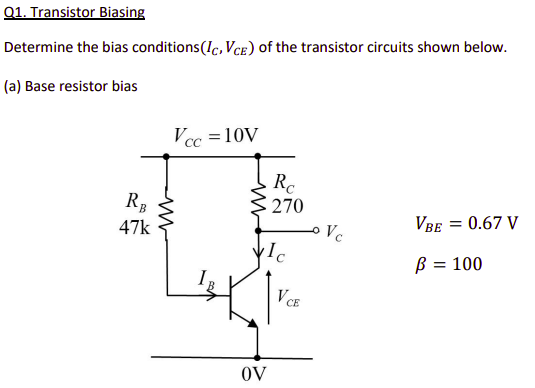

syms I_C V_CE I_B V_CC R_B R_C beta V_BE V_CE I_E

constants = [
    V_CC == 10
    R_B == 47e3
    R_C == 270
    beta == 100
    V_BE == 0.67
]

$$constants = \left(\begin{array}{c} V_{\mathrm{CC}}=10\\ R_{B}=47000\\ R_{C}=270\\ \beta =100\\ V_{\mathrm{BE}}=\frac{67}{100} \end{array}\right)$$


beta_relation = bjt_beta(beta, I_B, I_C, I_E)

$$beta\_relation = \left(\begin{array}{c} I_{C}=I_{B}\,\beta \\ I_{E}=I_{B}\,\left(\beta +1\right) \end{array}\right)$$

base_kvl = V_CC == I_B * R_B + V_BE

$$base\_kvl = V_{\mathrm{CC}}=V_{\mathrm{BE}}+I_{B}\,R_{B}$$

collector_kvl = V_CC == R_C * I_C + V_CE

$$collector\_kvl = V_{\mathrm{CC}}=V_{\mathrm{CE}}+I_{C}\,R_{C}$$


solve_for([I_C V_CE], [ ...
    constants

    beta_relation
    base_kvl
    collector_kvl
])

$$ans = \left(\begin{array}{cc} 0.01985 & 4.64 \end{array}\right)$$

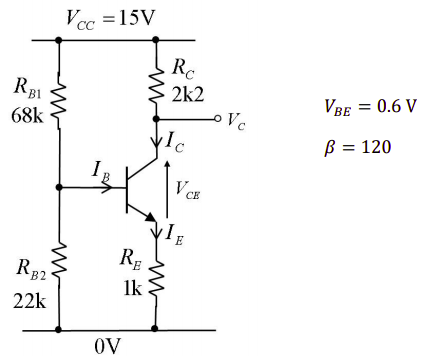

syms V_BB R_B1 R_B2 R_E

constants = [
    V_CC == 15
    R_B1 == 68e3
    R_B2 == 22e3
    R_C == 2.2e3
    beta == 120
    V_BE == 0.6
    R_E == 1e3
]

$$constants = \left(\begin{array}{c} V_{\mathrm{CC}}=15\\ R_{\mathrm{B1}}=68000\\ R_{\mathrm{B2}}=22000\\ R_{C}=2200\\ \beta =120\\ V_{\mathrm{BE}}=\frac{3}{5}\\ R_{E}=1000 \end{array}\right)$$


base_thev_res = R_B == zpar([R_B1 R_B2])

$$base\_thev\_res = R_{B}=\frac{R_{\mathrm{B1}}\,R_{\mathrm{B2}}}{R_{\mathrm{B1}}+R_{\mathrm{B2}}}$$

base_thev_v = V_BB == vdiv(V_CC, R_B1, R_B2)

$$base\_thev\_v = V_{\mathrm{BB}}=\frac{R_{\mathrm{B2}}\,V_{\mathrm{CC}}}{R_{\mathrm{B1}}+R_{\mathrm{B2}}}$$

base_kvl = V_BB == R_B * I_B + V_BE + R_E * I_E

$$base\_kvl = V_{\mathrm{BB}}=V_{\mathrm{BE}}+I_{B}\,R_{B}+I_{E}\,R_{E}$$

collector_kvl = V_CC == R_C * I_C + V_CE + R_E * I_E

$$collector\_kvl = V_{\mathrm{CC}}=V_{\mathrm{CE}}+I_{C}\,R_{C}+I_{E}\,R_{E}$$


solve_for([I_C V_CE], [ ...
    constants

    beta_relation
    base_thev_res
    base_thev_v
    base_kvl
    collector_kvl
])

$$ans = \left(\begin{array}{cc} 0.002674 & 6.421 \end{array}\right)$$

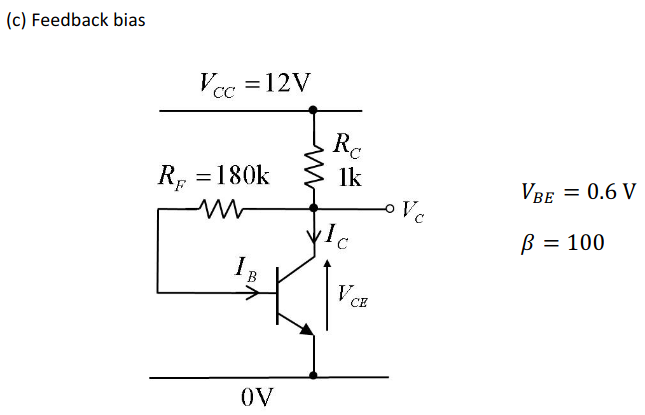

syms R_F
constants = [
    V_CC == 12
    R_F == 180e3
    R_C == 1e3
    V_BE == 0.6
    beta == 100
]

$$constants = \left(\begin{array}{c} V_{\mathrm{CC}}=12\\ R_{F}=180000\\ R_{C}=1000\\ V_{\mathrm{BE}}=\frac{3}{5}\\ \beta =100 \end{array}\right)$$


ce_kvl = V_CC == (I_C + I_B) * R_C + V_CE

$$ce\_kvl = V_{\mathrm{CC}}=V_{\mathrm{CE}}+R_{C}\,\left(I_{B}+I_{C}\right)$$

base_kvl = V_CE == I_B * R_F + V_BE

$$base\_kvl = V_{\mathrm{CE}}=V_{\mathrm{BE}}+I_{B}\,R_{F}$$


solve_for([I_C V_CE], [
    constants
    
    beta_relation
    ce_kvl
    base_kvl
])

$$ans = \left(\begin{array}{cc} 0.004057 & 7.902 \end{array}\right)$$

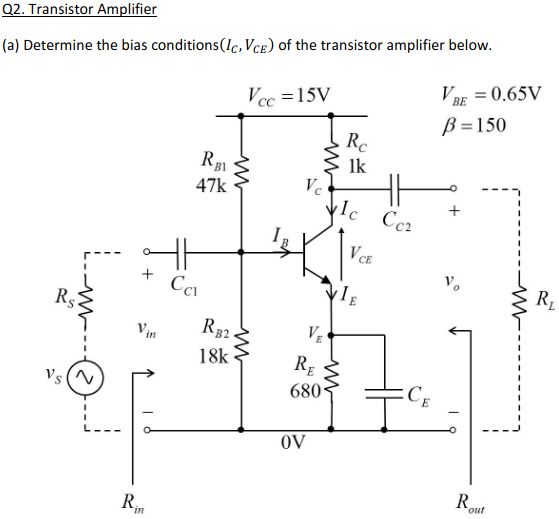

constants = [
    V_CC == 15
    R_B1 == 47e3
    R_B2 == 18e3
    R_C == 1e3
    R_E == 680
    V_BE == 0.65
    beta == 150
]

$$constants = \left(\begin{array}{c} V_{\mathrm{CC}}=15\\ R_{\mathrm{B1}}=47000\\ R_{\mathrm{B2}}=18000\\ R_{C}=1000\\ R_{E}=680\\ V_{\mathrm{BE}}=\frac{13}{20}\\ \beta =150 \end{array}\right)$$


base_thev_r = R_B == zpar([R_B1 R_B2])

$$base\_thev\_r = R_{B}=\frac{R_{\mathrm{B1}}\,R_{\mathrm{B2}}}{R_{\mathrm{B1}}+R_{\mathrm{B2}}}$$

base_thev_v = V_BB == vdiv(V_CC, R_B1, R_B2)

$$base\_thev\_v = V_{\mathrm{BB}}=\frac{R_{\mathrm{B2}}\,V_{\mathrm{CC}}}{R_{\mathrm{B1}}+R_{\mathrm{B2}}}$$

base_kvl = V_BB == I_B * R_B + V_BE + I_E * R_E

$$base\_kvl = V_{\mathrm{BB}}=V_{\mathrm{BE}}+I_{B}\,R_{B}+I_{E}\,R_{E}$$

ce_kvl = V_CC == I_C * R_C + I_E * R_E + V_CE

$$ce\_kvl = V_{\mathrm{CC}}=V_{\mathrm{CE}}+I_{C}\,R_{C}+I_{E}\,R_{E}$$


sol = solve_for([I_C V_CE R_B], [
    constants
    
    beta_relation
    base_thev_r
    base_thev_v
    base_kvl
    ce_kvl
])

$$sol = \left(\begin{array}{ccc} 0.004543 & 7.348 & 13020.0 \end{array}\right)$$

constants2 = [
    constants
    I_C == sol(1)
    V_CE == sol(2)
    R_B == sol(3)
];

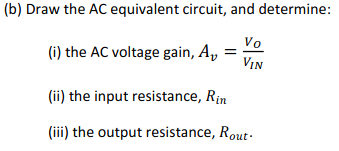

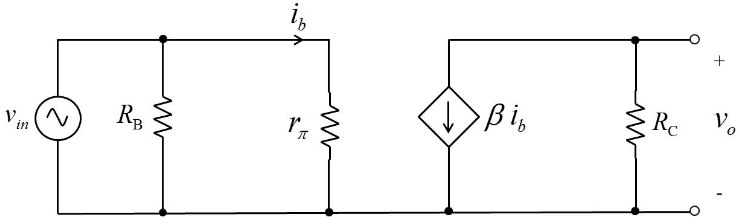

syms r_pi v_in v_o A_v i_b R_in R_out

% assume room temperature thermal voltage 0.025
diff_res = diffusion_resistance(beta, 0.025, I_C, r_pi)

$$diff\_res = I_{C}\,r_{\pi }=\frac{\beta }{40}$$

kvl_v_in = v_in == i_b * r_pi

$$kvl\_v\_in = v_{\mathrm{in}}=i_{b}\,r_{\pi }$$

kvl_v_out = v_o == -beta *  i_b * R_C

$$kvl\_v\_out = v_{o}=-R_{C}\,\beta \,i_{b}$$

gain = A_v == v_o / v_in

$$gain = A_{v}=\frac{v_{o}}{v_{\mathrm{in}}}$$

def_R_in = R_in == zpar([r_pi, R_B])

$$def\_R\_in = R_{\mathrm{in}}=\frac{R_{B}\,r_{\pi }}{R_{B}+r_{\pi }}$$

def_R_out = R_out == R_C

$$def\_R\_out = R_{\mathrm{out}}=R_{C}$$


sol = solve_for([A_v r_pi R_in R_out], [
    constants2
    
    diff_res
    kvl_v_in
    kvl_v_out
    gain
    def_R_in
    def_R_out
])

$$sol = \left(\begin{array}{cccc} -181.7 & 825.5 & 776.3 & 1000.0 \end{array}\right)$$

constants3 = [
    constants2
    A_v == sol(1)
    r_pi == sol(2)
    R_in == sol(3)
    R_out == sol(4)
];

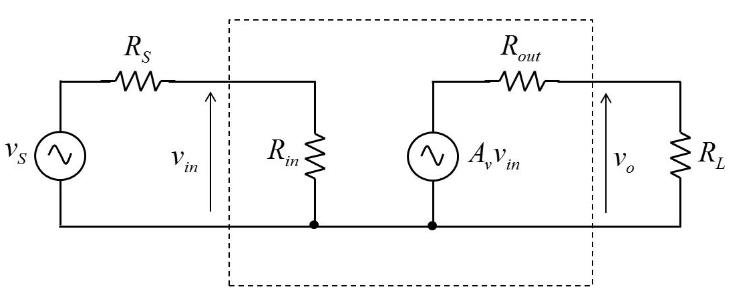

syms R_S R_L v_s gain

kvl_v_in = v_in == vdiv(v_s, R_S, R_in)

$$kvl\_v\_in = v_{\mathrm{in}}=\frac{R_{\mathrm{in}}\,v_{s}}{R_{S}+R_{\mathrm{in}}}$$

kvl_v_out = v_o == vdiv(A_v * v_in, R_out, R_L)

$$kvl\_v\_out = v_{o}=\frac{A_{v}\,R_{L}\,v_{\mathrm{in}}}{R_{L}+R_{\mathrm{out}}}$$

loaded_gain_eq = gain == v_o / v_s

$$loaded\_gain\_eq = \mathrm{gain}=\frac{v_{o}}{v_{s}}$$


sol = solve_for(gain, [
    constants3
    
    R_S == 1e3
    R_L == 5e3
    
    kvl_v_in
    kvl_v_out
    loaded_gain_eq
])

$$sol = -66.18$$

## Question 3

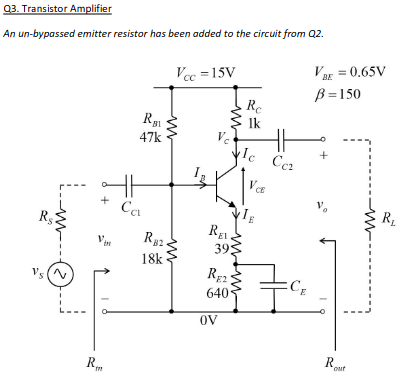

% everything is the same as Q2 on the dc side (almost)
% we are told in the question to assume its the same

syms R_E1 R_E2 R_E1_ib

% remove existing answers for A_v, R_out & R_in
constants4 = constants3

$$constants4 = \left(\begin{array}{c} V_{\mathrm{CC}}=15\\ R_{\mathrm{B1}}=47000\\ R_{\mathrm{B2}}=18000\\ R_{C}=1000\\ R_{E}=680\\ V_{\mathrm{BE}}=\frac{13}{20}\\ \beta =150\\ I_{C}=0.0045427648200870862638112157583237\\ V_{\mathrm{CE}}=7.3475612350739538669586181640625\\ R_{B}=13015.3846153914928436279296875\\ A_{v}=-181.71059280348345055244863033295\\ r_{\pi }=825.48847420371440072972506499523\\ R_{\mathrm{in}}=776.2552201573754988392109322437\\ R_{\mathrm{out}}=1000.0 \end{array}\right)$$

constants4(14) = []; % R_out
constants4(13) = []; % R_in
constants4(11) = []; % A_v

constants4 = [
    constants4
    R_E1 == 39
    R_E2 == 640
]

$$constants4 = \left(\begin{array}{c} V_{\mathrm{CC}}=15\\ R_{\mathrm{B1}}=47000\\ R_{\mathrm{B2}}=18000\\ R_{C}=1000\\ R_{E}=680\\ V_{\mathrm{BE}}=\frac{13}{20}\\ \beta =150\\ I_{C}=0.0045427648200870862638112157583237\\ V_{\mathrm{CE}}=7.3475612350739538669586181640625\\ R_{B}=13015.3846153914928436279296875\\ r_{\pi }=825.48847420371440072972506499523\\ R_{\mathrm{E1}}=39\\ R_{\mathrm{E2}}=640 \end{array}\right)$$

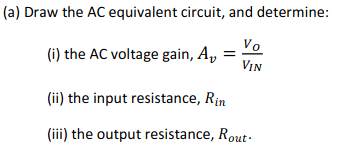

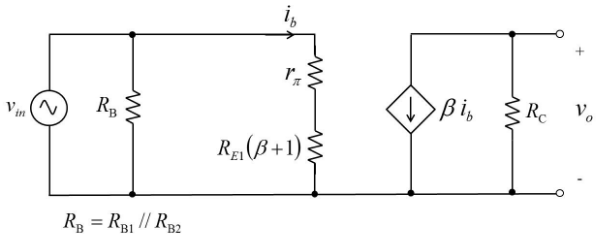

syms i_c i_e
beta_eq = bjt_beta(beta, i_b, i_c, i_e)

$$beta\_eq = \left(\begin{array}{c} i_{c}=\beta \,i_{b}\\ i_{e}=i_{b}\,\left(\beta +1\right) \end{array}\right)$$

kvl_v_in = v_in == i_b * r_pi + i_e * R_E1

$$kvl\_v\_in = v_{\mathrm{in}}=R_{\mathrm{E1}}\,i_{e}+i_{b}\,r_{\pi }$$

kvl_v_out = v_o == -i_c * R_C

$$kvl\_v\_out = v_{o}=-R_{C}\,i_{c}$$

gain_eq = A_v == v_o / v_in

$$gain\_eq = A_{v}=\frac{v_{o}}{v_{\mathrm{in}}}$$

def_R_in = R_in == zpar([r_pi + i_e * R_E1 / i_b, R_B])

$$def\_R\_in = R_{\mathrm{in}}=\frac{R_{B}\,\left(r_{\pi }+\frac{R_{\mathrm{E1}}\,i_{e}}{i_{b}}\right)}{R_{B}+r_{\pi }+\frac{R_{\mathrm{E1}}\,i_{e}}{i_{b}}}$$

def_R_out = R_out == R_C

$$def\_R\_out = R_{\mathrm{out}}=R_{C}$$


sol = solve_for([A_v R_in R_out v_in], [
    constants4
    
    R_S == 1e3
    R_L == 5e3
    
    beta_eq
    kvl_v_in
    kvl_v_out
    gain_eq
    def_R_in
    def_R_out
])

$$sol = \left(\begin{array}{cccc} -22.34 & 4429.0 & 1000.0 & -0.04476 \end{array}\right)$$

constants5 = [
    constants4
    A_v == sol(1)
    R_in == sol(2)
    R_out == sol(3)
]

$$constants5 = \left(\begin{array}{c} V_{\mathrm{CC}}=15\\ R_{\mathrm{B1}}=47000\\ R_{\mathrm{B2}}=18000\\ R_{C}=1000\\ R_{E}=680\\ V_{\mathrm{BE}}=\frac{13}{20}\\ \beta =150\\ I_{C}=0.0045427648200870862638112157583237\\ V_{\mathrm{CE}}=7.3475612350739538669586181640625\\ R_{B}=13015.3846153914928436279296875\\ r_{\pi }=825.48847420371440072972506499523\\ R_{\mathrm{E1}}=39\\ R_{\mathrm{E2}}=640\\ A_{v}=-22.33975090973535730742426937447\\ R_{\mathrm{in}}=4429.4076089856650509904044387211\\ R_{\mathrm{out}}=1000.0 \end{array}\right)$$

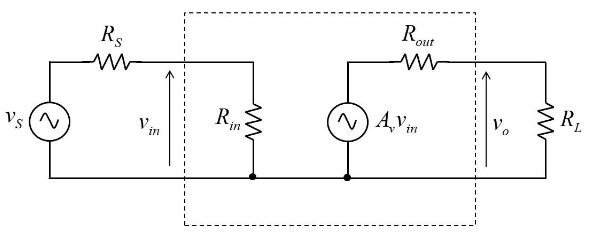

kvl_v_in = v_in == vdiv(v_s, R_S, R_in)

$$kvl\_v\_in = v_{\mathrm{in}}=\frac{R_{\mathrm{in}}\,v_{s}}{R_{S}+R_{\mathrm{in}}}$$

kvl_v_out = v_o == vdiv(A_v * v_in, R_out, R_L)

$$kvl\_v\_out = v_{o}=\frac{A_{v}\,R_{L}\,v_{\mathrm{in}}}{R_{L}+R_{\mathrm{out}}}$$

loaded_gain_eq = gain == v_o / v_s

$$loaded\_gain\_eq = \mathrm{gain}=\frac{v_{o}}{v_{s}}$$


sol = solve_for(gain, [
    constants5
    
    R_S == 1e3
    R_L == 5e3
    
    kvl_v_in
    kvl_v_out
    loaded_gain_eq
])

$$sol = -15.19$$

## Question 4

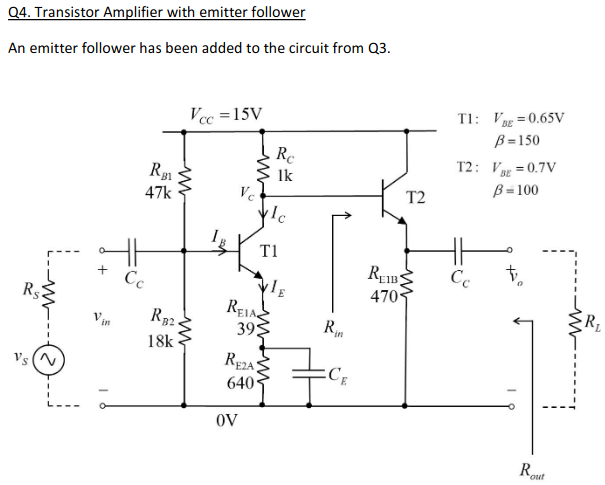

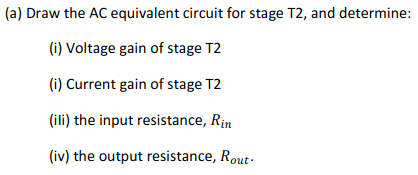

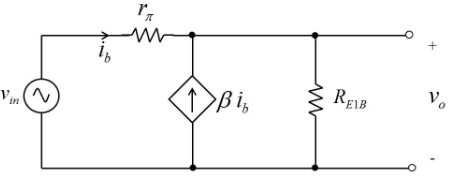

syms V_BE_2 beta_2 R_E1B i_e_2 i_b_2 i_c_2 A_v_2 A_i_2 r_pi_2 ...
    R_in_2 R_out_2 v_in_2 v_o_2
constants6 = constants5;
constants6(14:16) = []; % clear A_v, R_out, R_in

constants6 = [
    constants6
    
    V_BE_2 == 0.7
    beta_2 == 100
    R_E1B == 470
]

$$constants6 = \left(\begin{array}{c} V_{\mathrm{CC}}=15\\ R_{\mathrm{B1}}=47000\\ R_{\mathrm{B2}}=18000\\ R_{C}=1000\\ R_{E}=680\\ V_{\mathrm{BE}}=\frac{13}{20}\\ \beta =150\\ I_{C}=0.0045427648200870862638112157583237\\ V_{\mathrm{CE}}=7.3475612350739538669586181640625\\ R_{B}=13015.3846153914928436279296875\\ r_{\pi }=825.48847420371440072972506499523\\ R_{\mathrm{E1}}=39\\ R_{\mathrm{E2}}=640\\ V_{\mathrm{BE},2}=\frac{7}{10}\\ \beta_{2}=100\\ R_{\mathrm{E1B}}=470 \end{array}\right)$$


kvl_base_t2 = V_CC == R_C * (I_C + i_b_2) + V_BE_2 + i_e_2 * R_E1B

$$kvl\_base\_t2 = V_{\mathrm{CC}}=V_{\mathrm{BE},2}+R_{\mathrm{E1B}}\,i_{e,2}+R_{C}\,\left(I_{C}+i_{b,2}\right)$$

kvl_v_in = v_in_2 == r_pi_2 * i_b_2 + i_e_2 * R_E1B

$$kvl\_v\_in = v_{\mathrm{in},2}=R_{\mathrm{E1B}}\,i_{e,2}+i_{b,2}\,r_{\pi ,2}$$

kvl_v_out = v_o_2 == i_e_2 * R_E1B

$$kvl\_v\_out = v_{o,2}=R_{\mathrm{E1B}}\,i_{e,2}$$

bjt_t2 = bjt_beta(beta_2, i_b_2, i_c_2, i_e_2)

$$bjt\_t2 = \left(\begin{array}{c} i_{c,2}=\beta_{2}\,i_{b,2}\\ i_{e,2}=i_{b,2}\,\left(\beta_{2}+1\right) \end{array}\right)$$


gain_eq = A_v_2 == v_o_2 / v_in_2

$$gain\_eq = A_{v,2}=\frac{v_{o,2}}{v_{\mathrm{in},2}}$$

curr_gain_eq = current_voltage_gain(A_v_2, A_i_2, R_in, R_L)

$$curr\_gain\_eq = A_{v,2}=\frac{A_{i,2}\,R_{\mathrm{in}}}{R_{L}}$$

def_r_pi = diffusion_resistance(beta_2, 0.025, I_C_2, r_pi_2)

Unrecognized function or variable 'I_C_2'.


def_R_in = v_in_2 == R_in_2 * i_b_2
def_R_out = v_o_2 == R_out_2 * i_e

sol = solve_for([A_v_2 A_i_2 R_in_2 R_out_2], [
    constants6
    
    kvl_base_t2
    kvl_v_in
    kvl_v_out
    bjt_t2
    
    gain_eq
    curr_gain_eq
    def_r_pi
    
    def_R_in
    def_R_out
])